clear
filename = "model1.stl"

filename = "model6.stl"

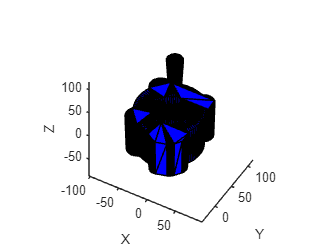

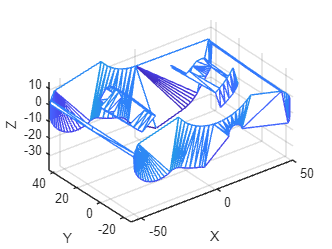

direction = [1 3 2];

model = stlread(filename);
% modelplot(model,direction);
[model1.ConnectivityList,model1.Points] = reducepatch(model.ConnectivityList,model.Points,5000);
model = model1;

clc

modelplot(model,direction);

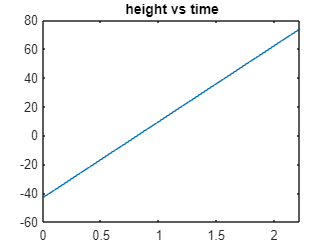

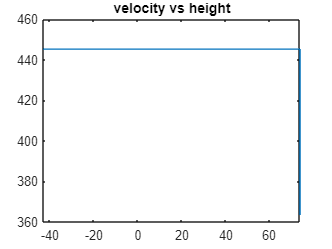

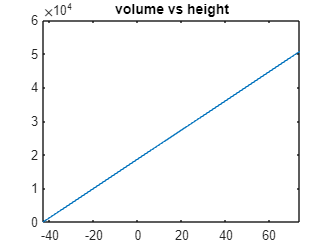

t = 2.2222


flowrate = 1.9294e5;
[t,h,v,volume,area] = filling_time_vel(model, direction, flowrate, 10);

% a stores all vertices in the STL model,
% m contains the connectivity list of faces
a = model.Points(:, direction);
m = model.ConnectivityList;

z_slice = 35;

[Am,P,Ac]=AREA_PERIMETER(model, direction, z_slice,"percentage")

Am = 8.6196e+03

P = 779.8199

Ac = 3.2988e+03

% Plot_cross_section(model, direction, z_slice,"percentage")

minA = 1000000000;
for i=35:2:100
    Plot_cross_section(model, direction, i,"percentage")
    [~,P,A]=AREA_PERIMETER(model, direction, i,"percentage");
    A/P
    minA(A<minA) = A;

end

ans = 4.2302

ans = 4.2084

ans = 8.3815

ans = 8.3856

ans = 8.3895

ans = 8.3934

ans = 8.3973

ans = 8.4011

ans = 8.5261

ans = 8.5322

ans = 8.5382

ans = 8.5441

ans = 4.3697

ans = 4.3152

ans = 4.2608

ans = 4.2064

ans = 4.1747

ans = 4.1242

ans = 3.9909

ans = 3.9654

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0

ans = 0